clear all;
%% крок подання аналогового сигналу [sec]
dt_sim=1e-4;
%% час моделювання [sec]
Tsim = 0.6; 
%% інтервали при яких відбуватиметься запис VMs(напруги мембрани) та PSCs ( імпульсів)[sec]
dt_out = 0.005; 
csim('set','dt',dt_sim);
%% створення 1-го імпульсного вхідного нейрону
n1 = csim('create','SpikingInputNeuron'); 
%% створення 2-го імпульсного вхідного нейрону
n2 = csim('create', 'SpikingInputNeuron'); 
%% створення 3-го імпульсного вхідного нейрону
n3 = csim('create', 'SpikingInputNeuron'); 
%% створення 1-го аналогового вхідного нейрону
n4 = csim('create','AnalogInputNeuron'); 
%% створення 2-го аналогового вхідного нейрону
n5 = csim('create','AnalogInputNeuron'); 
nmc = neural_microcircuit;

CSIM: network deleted.


%% створюється шар Sigmoidal нейрронів розміром 4х2х5, початкове положення на 3D – рафіку – 1, 1, 1 (х, y, z).
[nmc, p_sig]=add(nmc,'pool','type','SigmoidalNeuron','size',[4 2 5],'origin',[6 1 1]); 

Created 4x2x5 pool 1 (Frac_EXC=0.8, Iinject=1.35e-08-1.45e-08): 40 SigmoidalNeuron  


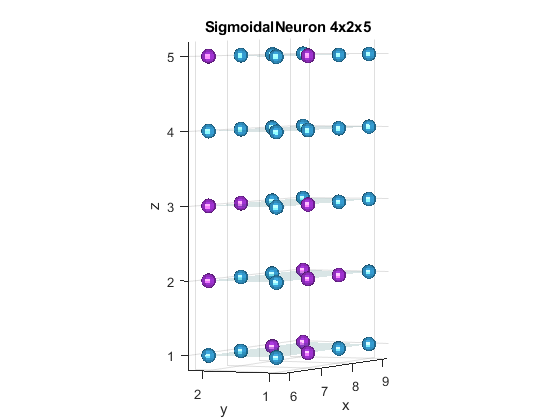

figure(1); %clf reset;
plat(nmc);
title('SigmoidalNeuron 4x2x5')

fprintf('SigmoidalNeuron 4x2x5 build\n');

SigmoidalNeuron 4x2x5 build


%% створюється шар Sigmoidal нейрронів розміром 2х3х4, початкове положення на 3D – рафіку – 6, 1, 1 (х, y, z).
[nmc, p_sig]=add(nmc,'pool','type','SigmoidalNeuron','size',[2 3 4],'origin',[6 1 1]); 

Created 2x3x4 pool 2 (Frac_EXC=0.8, Iinject=1.35e-08-1.45e-08): 24 SigmoidalNeuron  


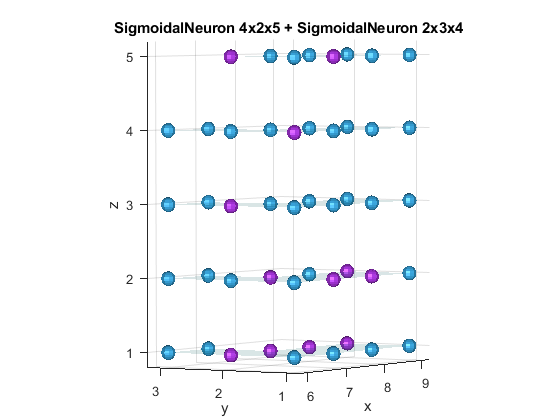

figure(2); %clf reset;
plat(nmc);
title('SigmoidalNeuron 4x2x5 + SigmoidalNeuron 2x3x4')

%fprintf('SigmoidalNeuron 2x3x4 build\n');
%% створюється шар LIF нейрронів розміром 2х3х4, початкове положення на 3D – рафіку – 6, 1, 1 (х, y, z).
[nmc, p_lif]=add(nmc,'pool','type','LifNeuron','size',[3 3 3],'origin',[10 1 1]); 

Created 3x3x3 pool 3 (Frac_EXC=0.8, Iinject=1.35e-08-1.45e-08): 27 LifNeuron  


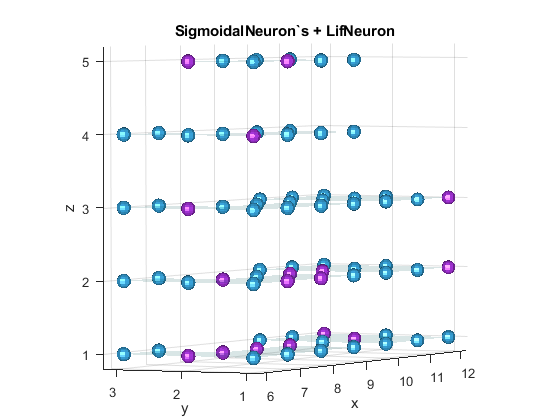

figure(3); %clf reset;
plat(nmc);
title('SigmoidalNeuron`s + LifNeuron')

%fprintf('SigmoidalNeuron + LifNeuron build\n');
%% створення двох імпульсних вхідних нейронів.
[nmc,p_sin] = add(nmc,'pool','type','SpikingInputNeuron',...
 'size',[1 1 3],'origin',[0 1 5],'frac_EXC',1.0);

Created 1x1x3 pool 4 (Frac_EXC=1, Iinject=1.35e-08-1.45e-08): 3 SpikingInputNeuron  


%% створення одного аналогового нейрону
[nmc,p_ain] = add(nmc,'pool','type','AnalogInputNeuron',...
 'size',[1 1 2],'origin',[0 1 2],'frac_EXC',1.0);

Created 1x1x2 pool 5 (Frac_EXC=1, Iinject=1.35e-08-1.45e-08): 2 AnalogInputNeuron  


p_sig = [6 1 1; 6 1 1];
p_sin = [0 1 5; 0 1 5];
%% з’єднання шарів
[nmc, c(1)] = add(nmc,'conn','dest', p_sig,'src', p_sin, 'Cscale',1,'Wscale',5); 

Created  connection 1 (Cscale=1, Wscale=5, SH_W=0.7, SH_UDF=0.5, SH_delay=0.1): 0 DynamicSpikingSynapse (lambda=Inf)


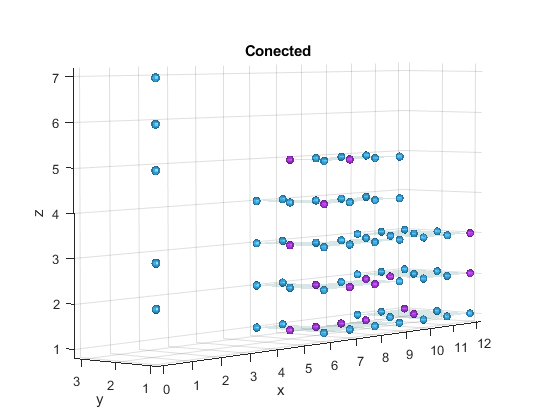

figure(2); %clf reset;
plat(nmc);
title('Conected');

%fprintf('SigmoidalNeuron + LifNeuron + SpikingInput + AnalogInput\n');